# Least Square

## Practice 1: Estimate left & right lane around ego vehicle

### Problem

There are pointclouds on both lanes around the vehicle acquired from a specific perception sensor.

If we can know the lanes around your vehicle, we can drive autonomously using lane information.

Use the least squre equation to extract lane's third-order information.

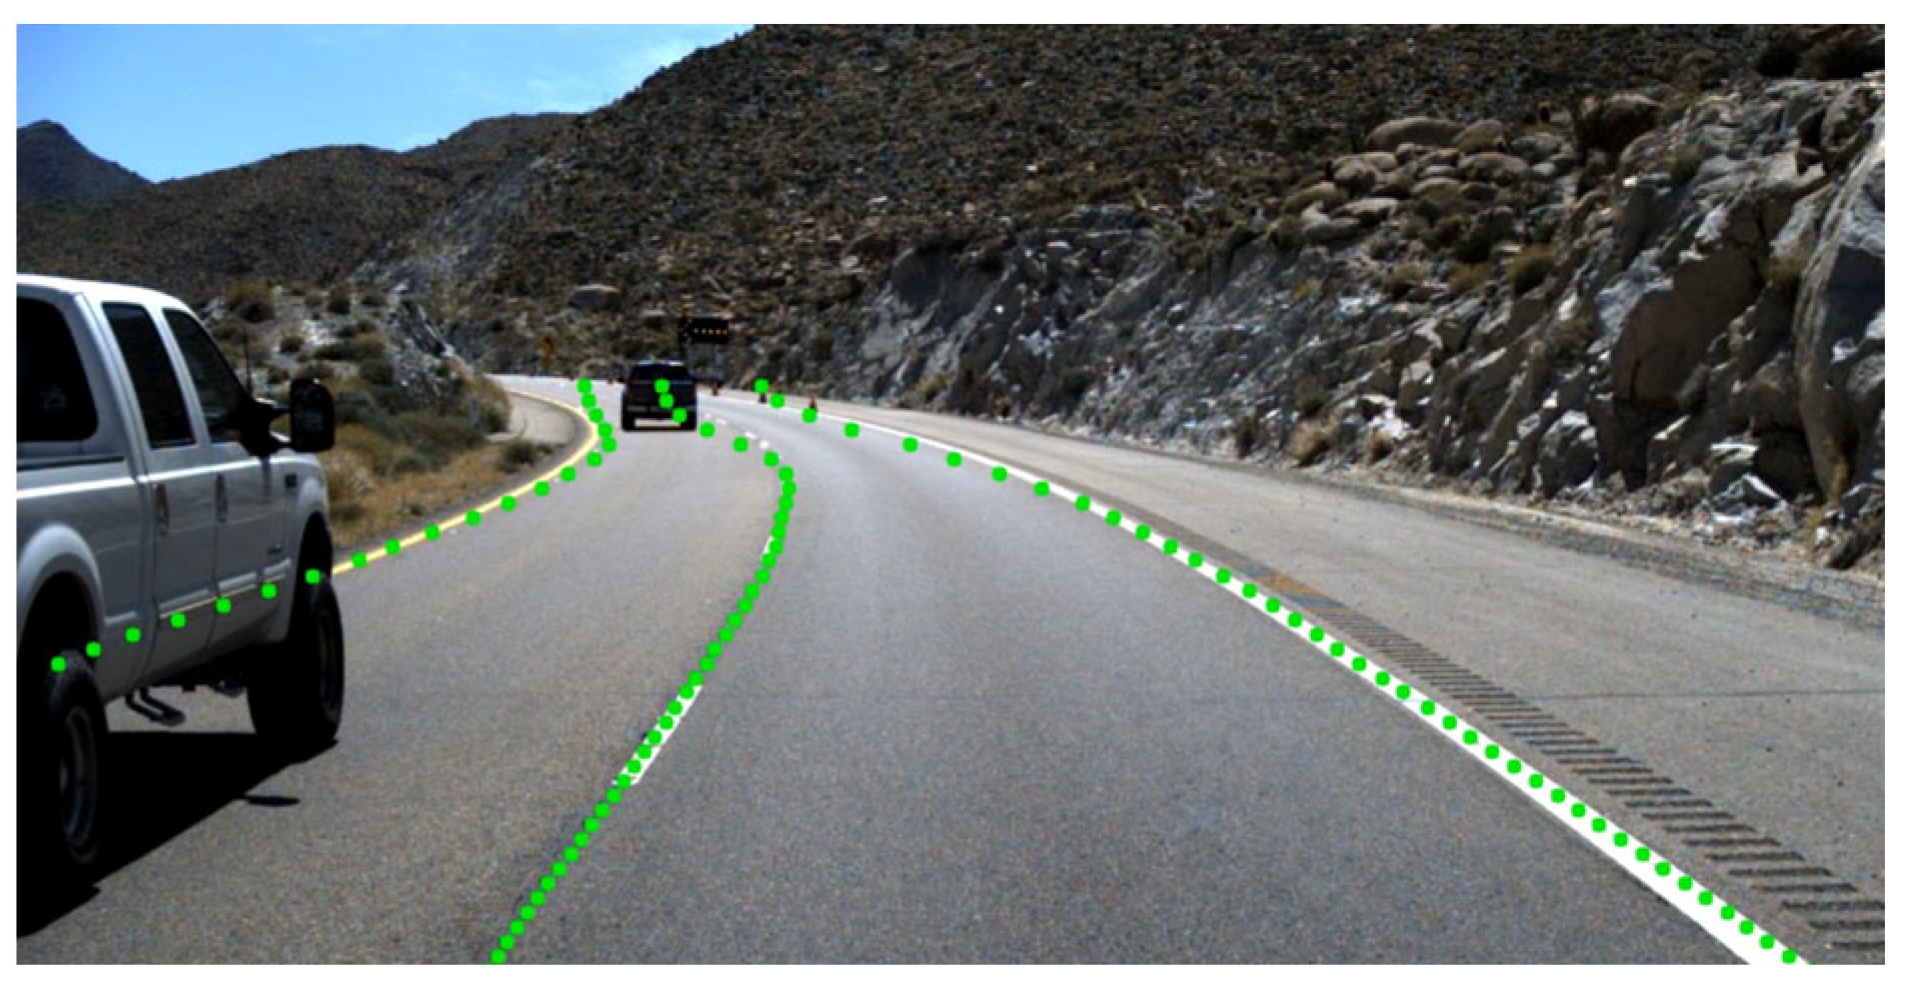

clear; close all;

% Load data from the CSV file
data_lane1 = readmatrix('/home/kmw/Downloads/matlabexercise/curve_lane_left.csv');
data_lane2 = readmatrix('/home/kmw/Downloads/matlabexercise/curve_lane_right.csv');

### Simulation Data Preprocessing & Visualization

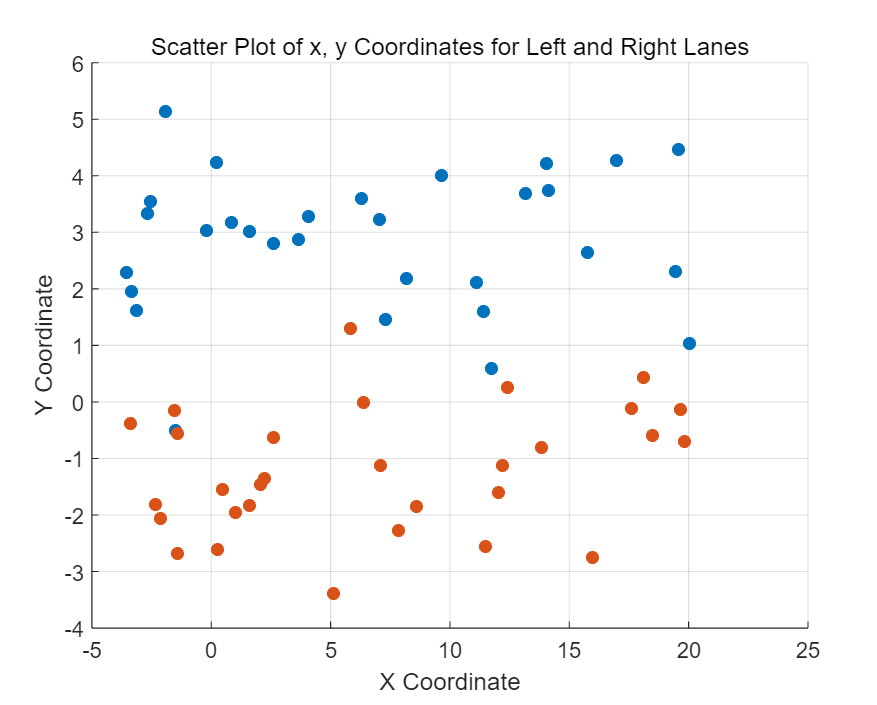

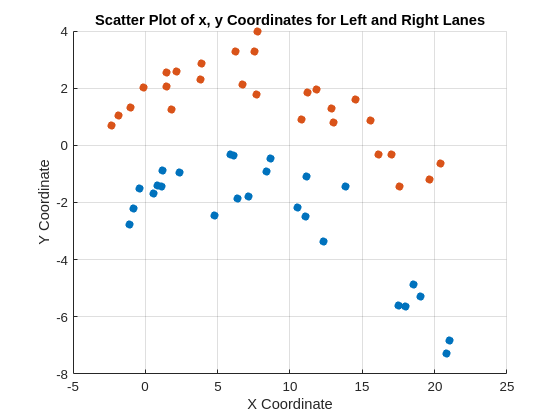

% Extract x and y coordinates for both lanes
x1 = data_lane1(:, 1);  % Assuming x c oordinates are in the first column
y1 = data_lane1(:, 2);  % Assuming y coordinates are in the second column

x2 = data_lane2(:, 1);  % Assuming x coordinates are in the first column
y2 = data_lane2(:, 2);  % Assuming y coordinates are in the second column

% Create a scatter plot of the data points for both lanes
figure;
scatter(x1, y1, 'filled', 'DisplayName', 'Left Lane Data');
hold on;
scatter(x2, y2, 'filled', 'DisplayName', 'Right Lane Data');

% Add titles and labels
title('Scatter Plot of x, y Coordinates for Left and Right Lanes');
xlabel('X Coordinate');
ylabel('Y Coordinate');
grid on;

### Least square modeling

Find the **a**, **b**, **c**, and **d** using simulation data through least square estimation.

A third-order equation of lane can be represented as follow: 

The description of this system can be written as follow:

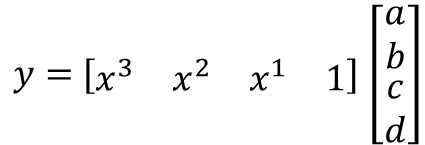

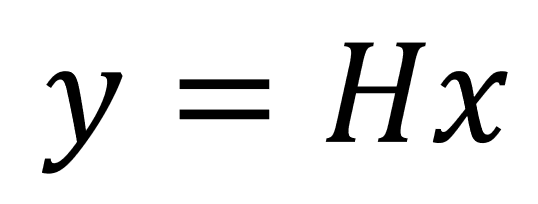

- y: measurement vector

- H: measurement matrix

- x: state vector

Num_of_state = 4; % a, b, c, d
H_left = zeros(length(x1), Num_of_state);
Y_left = zeros(length(x1), 1);
H_right = zeros(length(x2), Num_of_state);
Y_right = zeros(length(x2), 1);


% Get H matrix of left lane
%%%%%%% TODO %%%%%%%
%% Hint: For loop %%
for i = 1:length(x1)
    H_left(i, :) = [x1(i)^3, x1(i)^2, x1(i), 1];
end
%%%%%%%%%%%%%%%%%%%%

% Get Y vector of left lane
%%%%%%% TODO %%%%%%%
%% Hint: For loop %%
for i = 1:length(x1)
    Y_left(i) = y1(i);
end
%%%%%%%%%%%%%%%%%%%%


% Get H matrix of right lane
%%%%%%% TODO %%%%%%%
%% Hint: For loop %%
for i = 1:length(x2)
    H_right(i, :) = [x2(i)^3, x2(i)^2, x2(i), 1];
end
%%%%%%%%%%%%%%%%%%%%

% Get Y vector of right lane
%%%%%%% TODO %%%%%%%
%% Hint: For loop %%
for i = 1:length(x2)
    Y_right(i) = y2(i);
end
%%%%%%%%%%%%%%%%%%%%

### Solving least sqaure

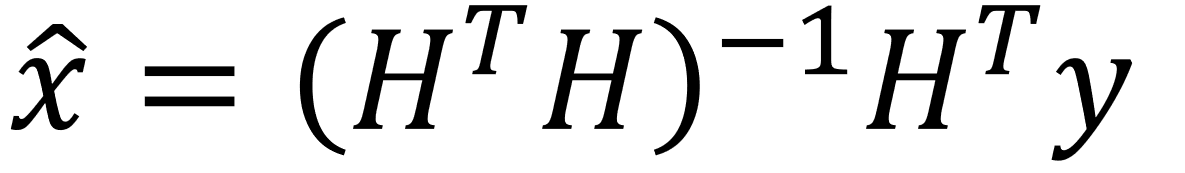

% Calculate least square 
%%%%%%% TODO %%%%%%%
% x_ls = XXXXXX ;
x_estimated_left = inv(H_left' * H_left) * H_left' * Y_left;
x_estimated_right = inv(H_right' * H_right) * H_right' * Y_right;
%%%%%%%%%%%%%%%%%%%%

% Calculate estimated value
%%%%%%% TODO %%%%%%%
y_estimated_left = H_left * x_estimated_left;
y_estimated_right = H_right * x_estimated_right;
%%%%%%%%%%%%%%%%%%%%

### Visualize result

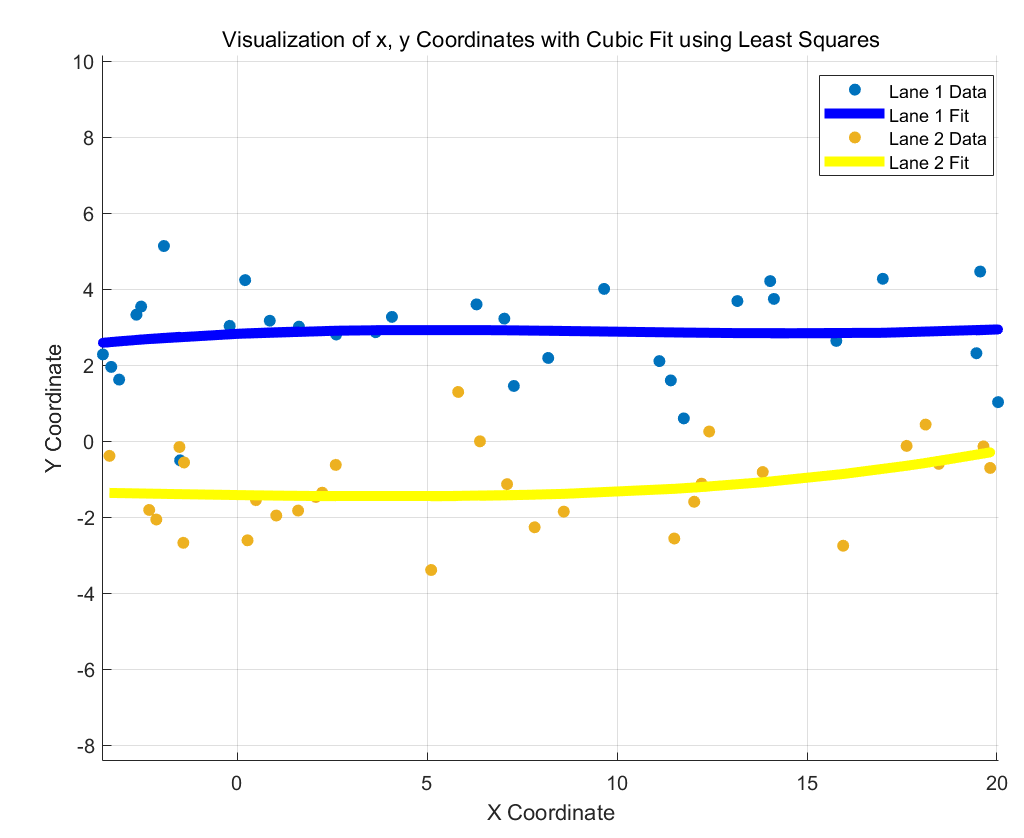

% Create a scatter plot of the data and the estimated curves
figure;
scatter(x1, y1, 'filled', 'DisplayName', 'Lane 1 Data');
hold on;
plot(x1, y_estimated_left, 'b-', 'LineWidth', 5, 'DisplayName', 'Lane 1 Fit');
scatter(x2, y2, 'filled', 'DisplayName', 'Lane 2 Data');
plot(x2, y_estimated_right, 'r-', 'LineWidth', 5, 'DisplayName', 'Lane 2 Fit');

title('Visualization of x, y Coordinates with Fit using Least Squares');
xlabel('X Coordinate');
ylabel('Y Coordinate');
grid on;

% Optionally, enhance visibility with axis equal if the data represents spatial coordinates
axis equal;

% Display the results
fprintf('Left Lane Cubic Fit coefficients (Least Squares) \n');

Left Lane Cubic Fit coefficients (Least Squares) 


fprintf('Estimated left lane coefficients: a: %f, b: %f, c: %f, d: %f\n', x_estimated_left(1), x_estimated_left(2), x_estimated_left(3), x_estimated_left(4));

Estimated left lane coefficients: a: 0.000193, b: -0.030601, c: 0.307089, d: -1.804188



fprintf('Right Lane Cubic Fit coefficients (Least Squares) \n');

Right Lane Cubic Fit coefficients (Least Squares) 


fprintf('Estimated right lane coefficients: a: %f, b: %f, c: %f, d: %f\n', x_estimated_right(1), x_estimated_right(2), x_estimated_right(3), x_estimated_right(4));

Estimated right lane coefficients: a: 0.000993, b: -0.047398, c: 0.402682, d: 1.811809


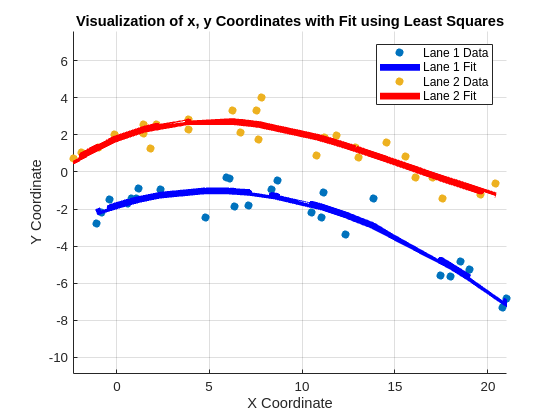


legend('Location', 'best');
hold off;